**Marine JOURNU**

**Lison LEANDRE**

**Sujet de mécanique des fluides**

**Question 1 :**

**a) **Nous cherchons à obtenir la solution analytique de I.

**Rappel de I : **$\frac{\textrm{dp}\left(y\right)}{\textrm{dy}}=\frac{\mu }{r}\;\frac{d}{\textrm{dr}}\left(r\frac{\textrm{dv}\left(r\right)}{\textrm{dr}}\right)$

Intégrons l'équation I par rapport à r en supposant que la pression varie linéairement le long de l'axe (dp/dy=K) :


$$K\int \mathrm{dr}=\mu \int \frac{1}{r}\;\frac{d}{\mathrm{dr}}\left(r\frac{\mathrm{dv}\left(r\right)}{\mathrm{dr}}\right)\mathrm{dr}$$



$$\textrm{Kr}=\mu \left(r\frac{\textrm{dv}\left(r\right)}{\textrm{dr}}-\int \frac{\textrm{dv}\left(r\right)}{\textrm{dr}}r\;\textrm{dr}\right)$$



$$\textrm{Kr}=\mu \left(r\;\frac{\textrm{dv}\left(r\right)}{\textrm{dr}}-\int v\left(r\right)\;\textrm{dr}\right)+C$$


$\textrm{Kr}=\mu \left(r\frac{\textrm{dv}\left(r\right)}{\textrm{dr}}-\frac{1}{2}v\left(r\right)r^2 \right)+C$ où C est une constante d'intégration. 

Maintenant, pour résoudre cette équation différentielle, supposons que v(0)=0 et v(r0)=V (vitesse maximale à r=0 et nulle à la paroi).

En utilisant ces conditions aux limites, nous pouvons déterminer C. 

Lorsque r=0, cela implique que C=0.

Maintenant nous allons résoudre l'équation différentielle en posant V=v(r).

Donc :


$$\textrm{Kr}=\mu \left(r\frac{\textrm{dV}}{\textrm{dr}}-\frac{1}{2}\textrm{Vr}\right)$$



$$\frac{1}{r}\textrm{dr}=\frac{\mu }{K}\left(\frac{\textrm{dV}}{\textrm{dr}}-\frac{1}{2}\frac{V}{r}\right)\textrm{dr}$$



$$\ln \left|r\right|=\frac{\mu }{K}\left(V-\frac{1}{2}\ln \left|r\right|\right)+C$$



$$\left|r\right|=e^{\frac{\mu }{K}V+C}$$



$$r=\frac{+}{}C\;e^{\frac{\mu }{K}V}$$


Nous utilisons de nouveau les conditions aux limites pour déterminer C. Nous utilisons v(r0)=V donc V=0.

Ce qui correspond bien à la condition v(0)=0 donc  $C=\frac{K}{4\mu }$ et alors $r=\frac{K}{4\mu }e^{\frac{\mu }{K}V}$ en choisissant la solution positive.

En substituant V nous obtenons bien :


$$v\left(r\right)=\frac{K}{4\mu }\left(r^2 -{\textrm{r0}}^2 \right)$$


**b)** Pour trouver le débit volumique Qv, nous intégrons la vitesse trouvée à la question précédente sur toute la section transversale du tube, de r=0 à r=r0 :


$$\textrm{Qv}=\int_0^{\textrm{r0}} v\left(r\right)*2\pi \;r\;\textrm{dr}$$


En remplaçant v(r) par la question a, nous obtenons :


$$\textrm{Qv}=-\frac{K}{2\mu }\pi \int_0^{\textrm{r0}} \left({\textrm{r0}}^2 r-r^3 \right)\;\textrm{dr}$$



$$\mathrm{Qv}=-\frac{K}{2\mu }\pi \left(\frac{{\mathrm{r0}}^4 }{2}-\frac{{\mathrm{r0}}^4 }{4}\right)$$



$$\mathrm{Qv}=\frac{K\pi }{2\mu }\left(-\frac{{\mathrm{r0}}^4 }{4}\right)$$


Donc nous retrouvons bien :


$$\textrm{Qv}=-\frac{\pi }{8\;\mu }\;K\;{\textrm{r0}}^4$$


**Question 2 a :**

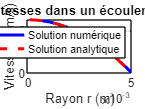

% Paramètres
r0 = 0.005;  % Rayon du tube en mètres
mu = 0.001;  % Viscosité du fluide en Pa.s
K = 1000;   % Gradient de pression en Pa/m
vmax = (K * r0^2) / (4 * mu);  % Vitesse maximale au centre

% Conditions initiales
r_min = 0.0001;  % Pour éviter la singularité à r = 0
v0 = vmax * (1 - (r_min/r0)^2);  % v(r) près de r = 0 basé sur l'analytique
u0 = 0;  % Dérivée de la vitesse à r = 0 (doit être nulle au maximum)

% Résolution numérique
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-8);
[r, v] = ode45(@tube_flow, [r_min r0], [v0 u0], options); %utilisation de la fonction ode45 comme déjà vu en cours

% Solution analytique pour comparaison
v_analytic = @(r) vmax * (1 - (r/r0).^2);

% Affichage graphique
figure;
plot(r, v(:,1), 'b-', 'LineWidth', 2);  % Solution numérique
hold on;
fplot(v_analytic, [r_min r0], 'r--', 'LineWidth', 2);  % Solution analytique
legend('Solution numérique', 'Solution analytique');
title('Comparaison des vitesses dans un écoulement laminaire de tube');
xlabel('Rayon r (m)');
ylabel('Vitesse v (m/s)');
grid on;



%on obtient une solution numérique et une solution analytique quasiment
%similaire ce qui indique que notre modèle est adapté à la résolution de ce
%problème.


Courbe similaire donc il s'agit d'une bonne solution

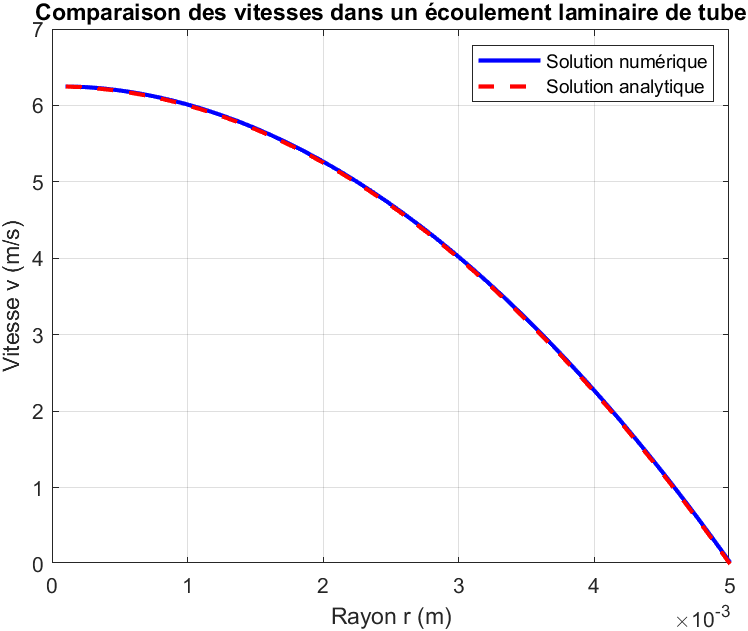

**Question 2 b : **

% Paramètres déjà définis
r0 = 0.005;  % Rayon du tube
mu = 0.001;  % Viscosité
K = 1000;    % Gradient de pression --> K positif

% Conditions initiales et résolution ODE
r_min = 0.0001;  % Début à partir d'un petit rayon pour éviter la singularité
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-8);
[r, v] = ode45(@tube_flow, [r_min r0], [v0 u0], options);

% Calcul numérique du débit volumique
Qv_numeric = trapz(r, 2 * pi * r .* v(:, 1));

% Débit volumique analytique pour comparaison
Qv_analytic = (K * pi * r0^4) / (8 * mu);

% Affichage des résultats
fprintf('Débit volumique numérique : %f m^3/s\n', Qv_numeric);

Débit volumique numérique : 0.000246 m^3/s


fprintf('Débit volumique analytique : %f m^3/s\n', Qv_analytic);

Débit volumique analytique : 0.000245 m^3/s



% on obtient après calculs des solutions très similaires

On retrouve bien quasiment la même valeur pour le débit volumique.

**Question 2 c : **

L'introduction de la gravité dans la nouvelle équation modifie considérablement le comportement de l'écoulement, en particulier lorsque le gradient de pression K est pris en compte. Examinons différents cas de figure en fonction de l'importance du gradient de pression et interprétons les résultats.

**Cas 1 : Gradient de pression dominant (****K élevé)**

Lorsque le gradient de pression K est dominant par rapport aux autres termes de l'équation, l'effet de la gravité peut être négligeable. Dans ce cas, l'écoulement sera principalement influencé par le gradient de pression, et la contribution de la gravité peut être considérée comme secondaire. 

**Cas 2 : Gravité dominante (****ρ****g**** élevé)**

Lorsque la gravité est dominante par rapport aux autres termes de l'équation, elle peut avoir un effet significatif sur l'écoulement. Dans ce cas, la gravité peut induire un profil de vitesse non négligeable, où la vitesse augmentera vers le bas du tube et diminuera vers le haut. Cependant, si le gradient de pression est suffisamment élevé pour compenser cet effet, l'écoulement peut toujours être principalement dirigé par le gradient de pression.

**Cas 3 : Équilibre entre gradient de pression et gravité**

L'écoulement peut être influencé par une combinaison de gradient de pression et gravité, conduisant à des profils de vitesse non linéaires et à des variations significatives de la pression le long du tube. 

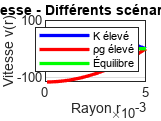

% paramètres
rho = 1000; % Masse volumique
g = 9.81; % Accélération due à la gravité
mu = 0.001;% Viscosité du fluide (Pa.s)
r0 = 0.005;% Rayon du tube (m)

% Scénarios
K_high = 10000;  % Cas 1: Gradient de pression élevé (K>rho*g)
rho_g_high = 2 * rho * g;  % Cas 2: Gravité dominante(rho*g>K)
K_balanced = rho * g;  % Cas 3: Équilibre entre gradient de pression et gravité(K=rho*g)

% Calcul de v(r) pour chaque scénario
v_K_high = (K_high / (4 * mu)) * (r0^2 - r.^2);
v_rho_g_high = (K / (4 * mu)) * (r0^2 - r.^2) - (rho_g_high * (r0^2 - r.^2)) / (4 * mu);
v_balanced = (K_balanced / (4 * mu)) * (r0^2 - r.^2) - (rho * g * (r0^2 - r.^2)) / (4 * mu);

figure;
plot(r, v_K_high, 'b', 'LineWidth', 2);
hold on;
plot(r, v_rho_g_high, 'r', 'LineWidth', 2);
plot(r, v_balanced, 'g', 'LineWidth', 2);
xlabel('Rayon r');
ylabel('Vitesse v(r)');
legend('K élevé', 'ρg élevé', 'Équilibre');
title('Profil de vitesse - Différents scénarios avec gravité');
grid on;